# Loading Dataset

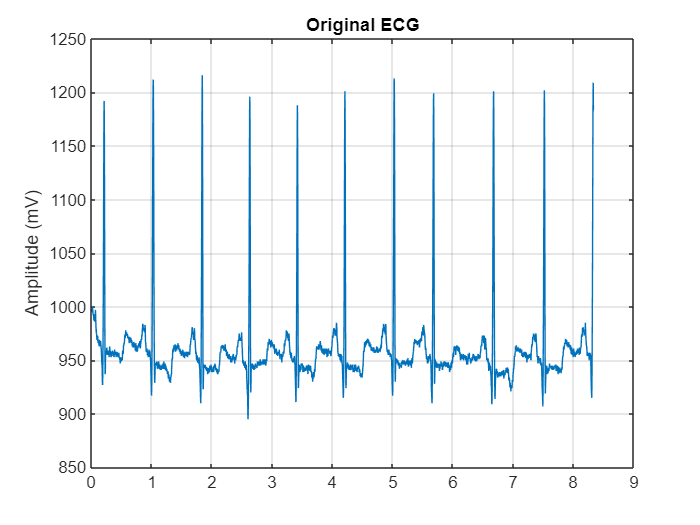

clc;
clear;
close all;

data = readmatrix('100.csv');
x = data(:,2);
x = x(:);
N = length(x);

fs = 360;
t = (0:N-1)/fs;

figure;
plot(t(1:3000), x(1:3000))
title('Original ECG')
ylabel('Amplitude (mV)')
grid on

# Adding WGN(White Gaussian Noise)

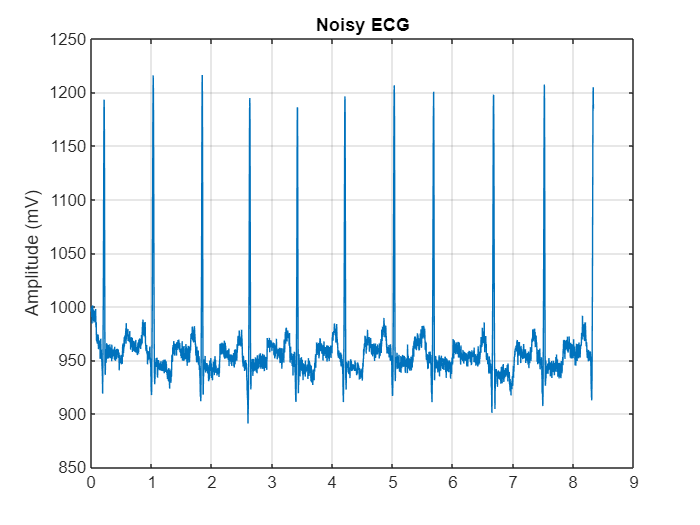

x_mean = mean(x);
noise = 0.1 * std(x) * randn(size(x));
x_noisy = (x - x_mean) + noise;

figure;
plot(t(1:3000), x_noisy(1:3000) + x_mean)
title('Noisy ECG')
ylabel('Amplitude (mV)')
grid on

# Decomposition

phi = [0.5 1 0.5];
psi = [1 0 -1];
phi = phi / norm(phi);
psi = psi / norm(psi);
L = length(phi);

levels = 3;
x_level = x_noisy;

%% Orthogonality Demonstration
dot_product = sum(phi .* psi);

fprintf('\nInner product between phi and psi = %.6f\n', dot_product);


Inner product between phi and psi = 0.000000



if abs(dot_product) < 1e-6
    disp('phi and psi are ORTHOGONAL');
else
    disp('phi and psi are NOT orthogonal');
end

phi and psi are ORTHOGONAL



% Check orthonormal condition
norm_phi = sum(phi.^2)

norm_phi = 1.0000

norm_psi = sum(psi.^2)

norm_psi = 1.0000

cA = cell(levels,1);
cD = cell(levels,1);

for i = 1:levels
    len = length(x_level);
    tempA = zeros(len,1);
    tempD = zeros(len,1);

    for k = 1:len
        for n = 1:L
            idx = k + n - 1;
            if idx <= len
                tempA(k) = tempA(k) + x_level(idx)*phi(n);
                tempD(k) = tempD(k) + x_level(idx)*psi(n);
            end
        end
    end

    cA{i} = tempA(1:2:end);
    cD{i} = tempD(1:2:end);
    x_level = cA{i};
end

for i = 1:levels
    len = min(length(cA{i}), length(cD{i}));
    corr_val = corr(cA{i}(1:len), cD{i}(1:len));
    
    fprintf('Correlation at level %d = %.6f\n', i, corr_val);
end

Correlation at level 1 = -0.000005
Correlation at level 2 = -0.000098
Correlation at level 3 = 0.001843
